% Problem 1
%construct matrx, get rhs
clear;
hilb15 = hilb(15);
x = ones(15,1);
b = hilb15 * x;
x_tilde = linsolve(hilb15, b);

rel_err_x = norm(x-x_tilde,2)/norm(x,2);

%compute svd
[U,S,V] =  svd(hilb15);
s = svd(hilb15);%singular value

%my way to do pseudoinv
T = diag(1./s);%reciprocal singular value and diagnize them
A_plus = V * T' * U';
x_plus = A_plus * b;
rel_err_x_plus = norm(x-x_plus,2)/norm(x,2);
temp = pinv(hilb15);
x_temp = temp * b;
rel_err_pin = norm(x-x_temp,2)/norm(x,2);

cond_num = s(1)/s(15);%condition number of A
fprintf('The conditioning number of A is %g', cond_num);

The conditioning number of A is 2.49595e+17

fprintf(['Relative error by linsolve method is %g\n' ...
    'Relative error by constructed pseudo-inverse is %g\n' ...
    'Relative error by pinv method is %g\n'], rel_err_x, rel_err_x_plus,rel_err_pin);

Relative error by linsolve method is 6.89686
Relative error by constructed pseudo-inverse is 3.06667
Relative error by pinv method is 0.00205518


% test my pinv using hilb(3)
clear;
A = hilb(3);
[U,S,V] = svd(A);
s = svd(A);
x = ones(3,1);
b = A*x;

T = diag(1./s);
A_plus = V * T' * U';
x_plus = A_plus * b;
rel_err_x_plus = norm(x-x_plus,2)/norm(x,2);
temp = pinv(A);
x_temp = temp * b;

rel_err_x_temp = norm(x-x_temp,2)/norm(x,2);
fprintf(['Relative error by constructed pseudo-inverse is %g\n' ...
    'Relative error by pinv method is %g\n'], rel_err_x_plus, rel_err_x_temp);

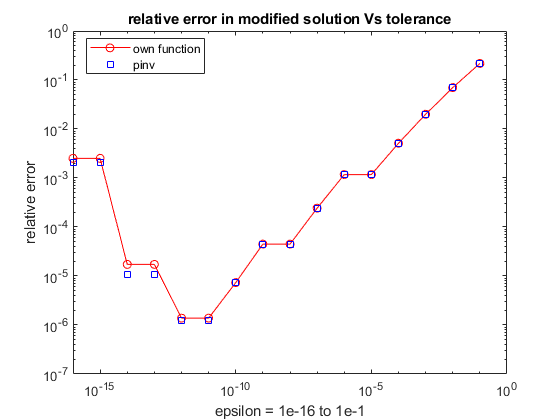

% Problem 1.2
clear;
A = hilb(15);
x = ones(15,1);
b = A * x;

%create epsilon
e = logspace(-16,-1,16);
rel_err = zeros(1,16);
rel_err_true = zeros(1,16);
for i = 1:16
    [compute, ture] = rpi(e(i),A,b,x);% call my function, the code is at the end of the file
    rel_err(i) = compute;
    rel_err_true(i) = ture;
end

figure(1);
loglog(e , rel_err, 'ro-', e, rel_err_true, 'bs');
ylim([1e-7 1]);
title('relative error in modified solution Vs tolerance');
xlabel('epsilon = 1e-16 to 1e-1');ylabel('relative error');
legend('own function', 'pinv', 'location', 'best');

% test my function rpi for epsilon = 0.1
A = hilb(15);
x = ones(15,1);
b = A * x;
e = 0.1;
s = svd(A);%singular value
[U,S,V] =  svd(A);
new_s = zeros(15,1);%regularized singular value
    for i = 1:15
        if s(i) < e*s(1)
            new_s(i) = 0;
        else
            new_s(i) = 1/s(i);
        end
    end
    %now we have the regularized singular value, computing x_tilde
    T = diag(new_s);
    A_tilde_plus = V * T' * U';
    x_tilde = A_tilde_plus * b;
    rel_err = norm(x-x_tilde,2)/norm(x,2);
    A_true = pinv(A, e*s(1));

% Problem 2
% Read the f i l e :
% test text harry potter
clear;
fid = fopen('harryPotter.txt','r'); txt = fread(fid); fclose(fid);
%convert to integers between 1 and 26
numtxt = upper(char(txt))-'A'+1;
%eliminate any weird characters
k=numtxt((numtxt >= 1) & (numtxt<=26));

A=zeros(26,26);
for n=1:length(k)-1
    j=k(n);
    i=k(n+1);
    A(i,j)=A(i,j)+1;
end

%normalization A
nor_A = A - min(A(:));
nor_A = nor_A ./ max(nor_A(:));

imagesc(nor_A);
colorbar;
title('normalized digraph matrix A');

% Problem 2.2
%rank-1 component and rank-2 component
[U,S,V] = svd(nor_A);
A_1 = S(1,1)*U(:,1)*(V(:,1))';
A_2 = S(2,2)*U(:,2)*(V(:,2))';
A_appro = A_1+A_2;
imagesc(A_1);
colorbar;
title('rank-1 component A1');
imagesc(A_2);
colorbar;
title('second principal component A2');
imagesc(A_appro);
colorbar;
title('rank-2 approximation fo matrix, A1+A2');

% Problem2.3
%using sum to get frequency of occurence
A_1_sum = sum(A_1);
imagesc(A_1_sum);
colorbar;
title('frequency of occurrence of the different letters');

% Problem2.4
%reorder rank-2
p = [1,5,9,15,21,25,2:4,6:8,10:14,16:20,22:24,26];
char(p+'A'-1);
temp = A_2;
for i=1:26
    for j=1:26
        A_2(i,j) = temp(p(i),p(j));
    end
end
imagesc(A_2);
colorbar;
title('reordered second principle component');


% test text latex wiki
% Problem 2
% Read the f i l e :
clear;
fid = fopen('latex.txt','r'); txt = fread(fid); fclose(fid);
%convert to integers between 1 and 26
numtxt = upper(char(txt))-'A'+1;
%eliminate any weird characters
k=numtxt((numtxt >= 1) & (numtxt<=26));

A=zeros(26,26);
for n=1:length(k)-1
    j=k(n);
    i=k(n+1);
    A(i,j)=A(i,j)+1;
end

%normalization A
nor_A = A - min(A(:));
nor_A = nor_A ./ max(nor_A(:));

imagesc(nor_A);
colorbar;
title('wiki-normalized digraph matrix A');

% Problem 2.2
[U,S,V] = svd(nor_A);
A_1 = S(1,1)*U(:,1)*(V(:,1))';
A_2 = S(2,2)*U(:,2)*(V(:,2))';
A_appro = A_1+A_2;
imagesc(A_1);
colorbar;
title('rank-1 component A1');
imagesc(A_2);
colorbar;
title('second principal component A2');
imagesc(A_appro);
colorbar;
title('rank-2 approximation fo matrix, A1+A2');

% Problem2.3
A_1_sum = sum(A_1);
imagesc(A_1_sum);
colorbar;
title('wiki-frequency of occurrence of the different letters');

% Problem2.4
p = [1,5,9,15,21,25,2:4,6:8,10:14,16:20,22:24,26];
char(p+'A'-1);
temp = A_2;
for i=1:26
    for j=1:26
        A_2(i,j) = temp(p(i),p(j));
    end
end
imagesc(A_2);
colorbar;
title('wiki-reordered second principle component');

% test text walden
% Problem 2
% Read the f i l e :
clear;
fid = fopen('walden.txt','r'); txt = fread(fid); fclose(fid);
%convert to integers between 1 and 26
numtxt = upper(char(txt))-'A'+1;
%eliminate any weird characters
k=numtxt((numtxt >= 1) & (numtxt<=26));

A=zeros(26,26);
for n=1:length(k)-1
    j=k(n);
    i=k(n+1);
    A(i,j)=A(i,j)+1;
end

%normalization A
nor_A = A - min(A(:));
nor_A = nor_A ./ max(nor_A(:));

imagesc(nor_A);
colorbar;
title('walden-normalized digraph matrix A');

% Problem 2.2
[U,S,V] = svd(nor_A);
A_1 = S(1,1)*U(:,1)*(V(:,1))';
A_2 = S(2,2)*U(:,2)*(V(:,2))';
A_appro = A_1+A_2;
imagesc(A_1);
colorbar;
title('rank-1 component A1');
imagesc(A_2);
colorbar;
title('second principal component A2');
imagesc(A_appro);
colorbar;
title('rank-2 approximation fo matrix, A1+A2');

% Problem2.3
A_1_sum = sum(A_1);
imagesc(A_1_sum);
colorbar;
title('walden-frequency of occurrence of the different letters');

% Problem2.4
p = [1,5,9,15,21,25,2:4,6:8,10:14,16:20,22:24,26];
char(p+'A'-1);
temp = A_2;
for i=1:26
    for j=1:26
        A_2(i,j) = temp(p(i),p(j));
    end
end
imagesc(A_2);
colorbar;
title('walden-reordered second principle component');

% figure combination
comb('2.1-1.png', '2.4-1.png', '2.5-1.png');
figure,imshow('2.5-1.png');
comb('2.1-5.png', '2.4-2.png', '2.5-2.png');
figure,imshow('2.5-2.png');
comb('2.1-6.png', '2.4-3.png', '2.5-3.png');
figure,imshow('2.5-3.png');

function C = comb(pic1,pic2,outputname)% this is the function to combine two figures
A = imread(pic1);
B = imread(pic2);
C = [A,B];
imwrite(C,outputname);
end
%this is the function to read in diferent epsilon and compute the
%regularized x_tilda
function [rel_err, rel_err_true] = rpi(e,A,b,x)
s = svd(A);%singular value
[U,S,V] =  svd(A);
new_s = zeros(15,1);%regularized singular value
    for i = 1:15
        if s(i) < e*s(1)
            new_s(i) = 0;
        else
            new_s(i) = 1/s(i);
        end
    end
    %now we have the regularized singular value, computing x_tilde
    T = diag(new_s);
    A_tilde_plus = V * T' * U';
    x_tilde = A_tilde_plus * b;
    rel_err = norm(x-x_tilde,2)/norm(x,2);
    
    A_true = pinv(A, e*s(1));
    x_true = A_true * b;
    rel_err_true = norm(x-x_true,2)/norm(x,2);
end